DAC Range

dac_input = [0 0.206451612903226 0.412903225806452 0.619354838709677 0.825806451612903 1.03225806451613 1.23870967741935 1.44516129032258 1.65161290322581 1.85806451612903 2.06451612903226 2.27096774193548 2.47741935483871 2.68387096774194 2.89032258064516 3.09677419354839 3.3];

dac_unbuff_no_load = [0.00029 0.05771 0.08159 0.1104 0.14257 0.17767 0.21611 0.25702 0.29951 0.3399 0.38418 0.42398 0.47831 0.8307 3.3212 3.3161 3.318];
dac_buff_no_load = [0.00384 0.20963 0.42009 0.6297 0.8366 1.0469 1.2543 1.462 1.6696 1.8732 2.0801 2.287 2.4899 2.6869 2.8172 2.8217 2.8304];

dac_unbuff_loaded = [0.00029 0.8202 1.0443 1.2606 1.4713 1.6842 1.8941 2.0981 2.307 2.5125 2.7173 2.9261 3.131 3.2658 3.262 3.252 3.2683];
dac_buff_loaded = [0.00002 0.20509 0.41189 0.6178 0.8227 1.0291 1.2318 1.4325 1.6364 1.8371 2.0325 2.2334 2.4415 2.5491 2.5788 2.579 2.5854];

figure();
plot(dac_input, dac_unbuff_no_load, 'm-x', dac_input, dac_buff_no_load, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output voltage versus DAC input", "voltage with no load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_no_load(end), sprintf('%.2f', dac_buff_no_load(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_no_load.png');

figure();
plot(dac_input, dac_unbuff_loaded, 'm-x', dac_input, dac_buff_loaded, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output voltage versus DAC input", "voltage with maximum load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_loaded(end), sprintf('%.2f', dac_buff_loaded(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_loaded.png');

dac_input = dac_input(1:13);
dac_buff_no_load = dac_buff_no_load(1:13);
dac_buff_loaded = dac_buff_loaded(1:13);

coefficients_no_load = polyfit(dac_input, dac_buff_no_load, 1);
m_no_load = coefficients_no_load(1)
b_no_load = coefficients_no_load(2)
r = corrcoef(dac_input, dac_buff_no_load);
r_2_no_load = r(1,2)^2

coefficients_no_load = polyfit(dac_input, dac_buff_loaded, 1);
m_loaded = coefficients_no_load(1)
b_loaded = coefficients_no_load(2)
r = corrcoef(dac_input, dac_buff_loaded);
r_2_loaded = r(1,2)^2

ADC range

adc_multimeter = [0.00299 0.20852 0.41849 0.6282 0.8363 1.0419 1.2487 1.4556 1.6649 1.8689 2.0821 2.2859 2.4966 2.6888];
adc_bits = [0.00483516483516484 0.20952380952381 0.425494505494506 0.626153846153846 0.817142857142857 1.05648351648352 1.26117216117216 1.42315018315018 1.66168498168498 1.88087912087912 2.05575091575092 2.27172161172161 2.45465201465201 2.66095238095238];

figure();
plot(adc_multimeter, adc_bits, 'b-x');
xlabel('Multimeter Voltage (V)');
ylabel('ADC Voltage (V)');
title(["DAC output measured using the ADC", "versus using the multimeter"], "FontSize", 22);
saveas(gcf, 'Report/Figures/Testing/ADC.png');

coefficients_adc = polyfit(adc_multimeter, adc_bits, 1);
m_adc = coefficients_adc(1)
b_adc = coefficients_adc(2)
r = corrcoef(adc_multimeter, adc_bits);
r_adc = r(1,2)^2

Resistors

R = [0.02 1 1.21 1.52 1.88 2.26 2.68 3.42 3.85 4.84 5.59 6.72 7.49 8.2 9.9];
vr_ave = [1.04 1.95 2.13 2.42 2.7 3.06 3.45 4.09 4.48 5.35 5.96 6.91 7.52 8.09 9.39]/5;
vr_sin = [1.03 1.94 2.11 2.4 2.69 3.04 3.44 4.08 4.47 5.35 5.96 6.91 7.52 8.1 9.4]/5;

r = corrcoef(vr_ave, vr_sin);
r_r = r(1,2)^2

k = vr_ave * 5/105;
rm = k*100./(1-k);

% curveFitter(R, vr_ave)

r = corrcoef(R, rm);
r_rv = r(1,2)^2

figure();
plot(R, rm, 'bx');
xlabel('Multimeter Resistance (Ω)');

ylabel('Probe Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_uncorrected.png');

% (p1*x + p2)/(x + q1)
P1 = 17.4687;
P2 = 18.4643;
Q1 = 91.8315;

r_corr = (P2 - Q1 * vr_ave)./(vr_ave - P1);

figure();
plot(R, r_corr, 'b-x');
xlabel('Multimeter Resistance (Ω)');
ylabel('Prove Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter", "using the corrected equation"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_corrected.png');

coefficients_r = polyfit(R, r_corr, 1);
m_r = coefficients_r(1)
b_r = coefficients_r(2)

r = corrcoef(R, r_corr);
r_r_corr = r(1,2)^2

Voltage to Conductivity    

figure();
hold on
[a, b, r2] = map("150,596,348,881;182,724,421,1037;215,855,495,1218;248,987,570,1374;281,1119,646,1560;314,1250,720,1713;346,1379,793,1860;379,1510,868,2021;412,1642,943,2188;445,1774,1018,2346;478,1906,1093,2517;510,2033,1167,2680;543,2165,1241,2850;576,2297,1316,3021;609,2429,1391,3181;642,2561,1466,3341;674,2689,1539,3491;707,2821,1614,3630;740,2952,1688,3769;773,3084,1763,3865;")

a = 201.2321

b = 2.2039

r2 = 0.9676

[a, b, r2] = map("150,596,348,880;182,724,421,1051;215,855,495,1216;248,987,571,1375;281,1119,646,1554;314,1251,720,1705;346,1379,793,1862;379,1510,868,2027;412,1642,941,2200;445,1774,1018,2358;478,1905,1094,2522;510,2033,1167,2680;543,2165,1241,2856;576,2297,1316,3022;609,2429,1391,3187;642,2561,1466,3349;674,2689,1539,3501;707,2821,1613,3654;740,2952,1688,3778;773,3084,1764,3870;")

a = 203.0230

b = 2.2060

r2 = 0.9841

[a, b, r2] = map("150,596,348,888;182,724,421,1056;215,855,495,1228;248,986,570,1396;281,1119,646,1575;314,1251,720,1726;346,1378,794,1885;379,1510,868,2050;412,1641,943,2212;445,1774,1018,2371;478,1905,1094,2535;510,2033,1166,2699;543,2165,1241,2848;576,2297,1316,3023;609,2429,1391,3200;642,2561,1466,3368;674,2689,1539,3514;707,2821,1614,3655;740,2952,1689,3776;773,3084,1763,3876;")

a = 217.6936

b = 2.2126

r2 = 0.9683

[a, b, r2] = map("150,596,348,904;182,724,421,1076;215,855,495,1243;248,987,571,1409;281,1119,646,1578;314,1250,720,1745;346,1379,793,1907;379,1510,868,2066;412,1642,943,2250;445,1773,1018,2405;478,1905,1094,2553;510,2033,1166,2709;543,2165,1241,2875;576,2297,1316,3038;609,2429,1392,3203;642,2561,1466,3362;674,2689,1539,3535;707,2821,1613,3684;740,2952,1688,3808;773,3084,1763,3906;")

a = 239.0822

b = 2.2204

r2 = 0.9780

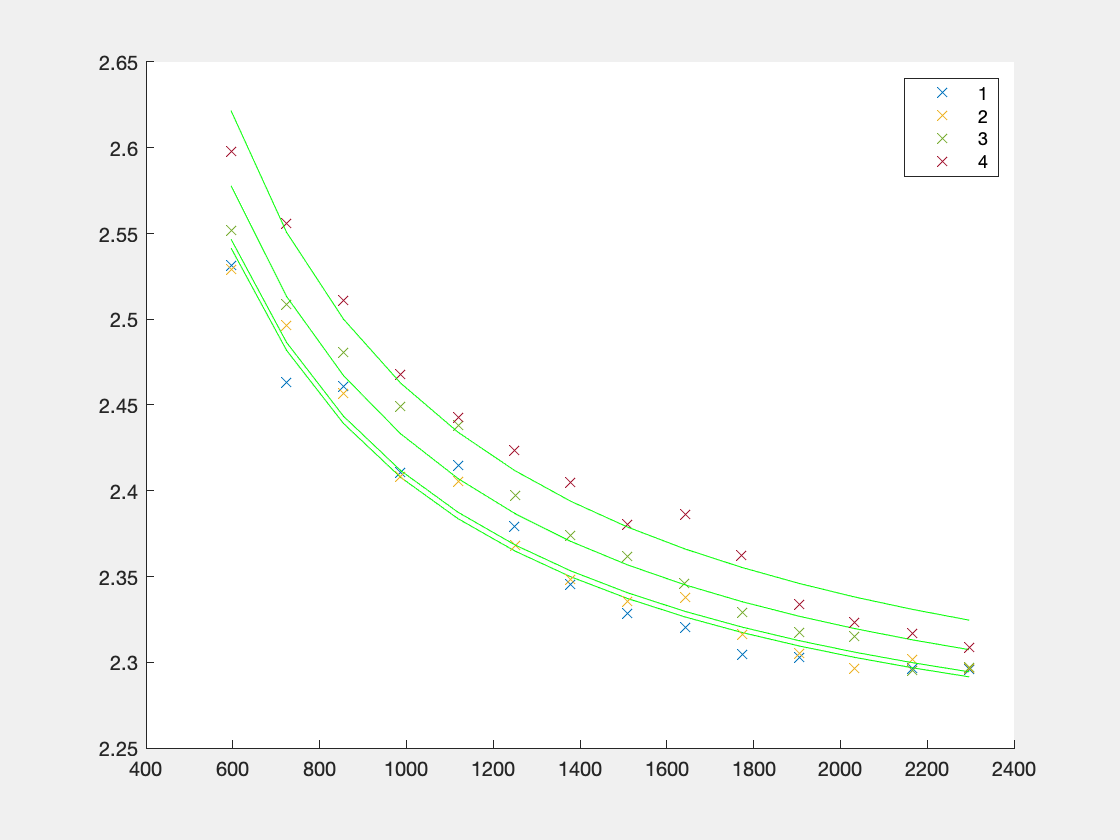

hold off
legend(["1","","2","","3","","4",""])

figure();
hold on
[a, b, r2] = map("150,596,348,759;182,724,421,970;215,855,496,1185;248,987,571,1395;281,1119,645,1600;314,1251,721,1785;346,1379,793,1947;379,1510,868,2127;412,1642,943,2315;445,1774,1018,2485;478,1906,1094,2675;510,2033,1167,2846;543,2165,1241,3028;576,2297,1317,3345;609,2428,1392,3401;642,2561,1467,3751;674,2689,1540,3750;707,2820,1614,3856;740,2952,1689,3935;773,3084,1764,4011;")

a = -196.9063

b = 2.5847

r2 = 0.7233

[a, b, r2] = map("150,596,348,955;182,723,421,1130;215,855,496,1322;248,986,571,1502;281,1119,646,1656;314,1251,721,1827;346,1379,794,1999;379,1510,869,2182;412,1642,945,2421;445,1774,1020,2536;478,1905,1095,2742;510,2033,1168,2879;543,2165,1242,3061;576,2297,1319,3243;609,2429,1394,3447;642,2561,1468,3553;674,2689,1542,3710;707,2821,1616,3840;740,2952,1691,3929;773,3085,1767,4004;")

a = 234.5763

b = 2.3653

r2 = 0.9420

[a, b, r2] = map("150,596,349,939;182,724,422,1114;215,855,496,1311;248,987,572,1487;281,1119,646,1669;314,1251,722,1843;346,1379,795,2020;379,1511,870,2197;412,1642,944,2381;445,1774,1019,2555;478,1905,1095,2741;510,2033,1168,2919;543,2165,1243,3100;576,2297,1318,3261;609,2429,1393,3422;642,2561,1468,3601;674,2689,1542,3754;707,2821,1617,3879;740,2952,1692,3957;773,3085,1767,4019;")

a = 173.2386

b = 2.4142

r2 = 0.9704

[a, b, r2] = map("150,596,348,1030;182,724,421,1208;215,855,496,1389;248,987,571,1560;281,1119,646,1732;314,1251,721,1918;346,1379,794,2077;379,1510,869,2258;412,1642,944,2423;445,1773,1019,2597;478,1905,1094,2773;510,2033,1167,2949;543,2166,1241,3136;576,2297,1317,3313;609,2429,1392,3491;642,2561,1467,3660;674,2688,1540,3799;707,2821,1615,3894;740,2952,1689,3973;773,3085,1764,4026;")

a = 373.9203

b = 2.3479

r2 = 0.9958

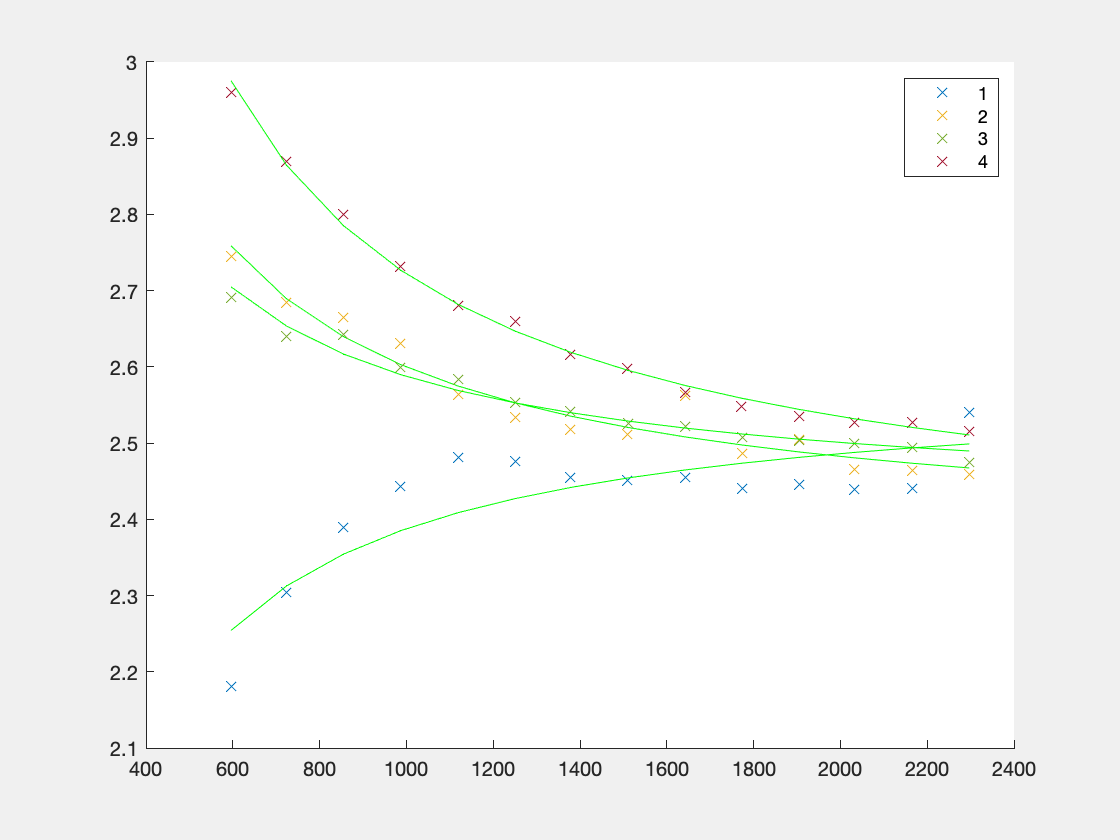

hold off
legend(["1","","2","","3","","4","",])

% [a, b, r2] = map("")
S(1/2.5, 1/2.30, 20.4, 0)

ans = 27.9303

function [a, b, r_squared] = map(sample)
    cols = strsplit(sample, ";");
    cols = cols(1:end-1);
    data = [];
    for i = 1:length(cols)
        data = [data; strsplit(cols(i), ",")];
        if (str2double(data(i,2)) > 2250)
            break;
        end
    end
    dac = str2double(data(:,2));
    ratio = str2double(data(:,4))./str2double(data(:,3));

    % curveFitter(dac, ratio)

    ft = fittype("a/x + b", 'option', fitoptions('Method', 'NonlinearLeastSquares', 'StartPoint', [0,0]));
    [fitresult, gof] = fit(dac, ratio, ft);
    
    a = fitresult.a;
    b = fitresult.b;
    r_squared = gof.rsquare;

    plot(dac, ratio, 'x', dac, fitresult(dac), 'g-')
    set(gcf, 'Visible', 'on');
end

function C = S(conductivity, std_conductivity, temperature, pressure)
CONST_K = 0.0162;

CONST_A_0 = 0.0080;
CONST_A_1 = -0.1692;
CONST_A_2 = 25.3851;
CONST_A_3 = 14.0941;
CONST_A_4 = -7.0261;
CONST_A_5 = 2.7081;

CONST_B_0 = 0.0005;
CONST_B_1 = -0.0056;
CONST_B_2 = -0.0066;
CONST_B_3 = -0.0375;
CONST_B_4 = 0.0636;
CONST_B_5 = -0.0144;

CONST_C_0 = 0.6766097;
CONST_C_1 = 0.0200564;
CONST_C_2 = 0.0001104259;
CONST_C_3 = -0.00000069698;
CONST_C_4 = 0.0000000010031;

CONST_D_1 = 0.03426;
CONST_D_2 = 0.0004464;
CONST_D_3 = -0.004215;
CONST_D_4 = -0.003107;

CONST_E_1 = 0.00002070;
CONST_E_2 = -0.000000006370;
CONST_E_3 = 0.000000000000003989;

R = conductivity / std_conductivity;
r_t = CONST_C_0 + CONST_C_1 * temperature + CONST_C_2 * temperature * temperature + CONST_C_3 * temperature * temperature * temperature + CONST_C_4 * temperature * temperature * temperature * temperature;
R_p = 1 + (CONST_E_1 * pressure + CONST_E_2 * pressure * pressure + CONST_E_3 * pressure * pressure * pressure) / (1 + CONST_D_1 * temperature + CONST_D_2 * temperature * temperature + R * (CONST_D_3 + CONST_D_4 * temperature));
R_t = R / (R_p * r_t);
C = CONST_A_0 + CONST_A_1 * (R_t ^ 0.5) + CONST_A_2 * R_t + CONST_A_3 * (R_t ^ 1.5) + CONST_A_4 * R_t * R_t + CONST_A_5 * (R_t ^ 2.5) + (temperature - 15) / (1 + CONST_K * (temperature - 15)) * (CONST_B_0 + CONST_B_1 * (R_t ^ 0.5) + CONST_B_2 * R_t + CONST_B_3 * (R_t ^ 1.5) + CONST_B_4 * R_t * R_t + CONST_B_5 * (R_t ^ 2.5));
end